clear;clc;

netlist={
    uA741('0','e-','out')
    'R1 e- out 29e3'
    'C1 out d1 6.5e-8'
    'R3 0 d1 1e3'
    'C2 d1 d2 6.5e-8'
    'R4 0 d2 1e3'
    'C3 d2 d3 6.5e-8'
    'R2 d3 e- 1e3'
    '.tran tstop=10 dtmax=1e-5 initTRAN=CI'
    '.probe out d3'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000

sim = struct with fields:
           X_t: [34×200000 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {2×1 cell}
      probe_id: [11 7]
         names: {1×34 cell}


f = 1/(2*pi*1e3*6.5e-8*sqrt(6))

f = 408.6461

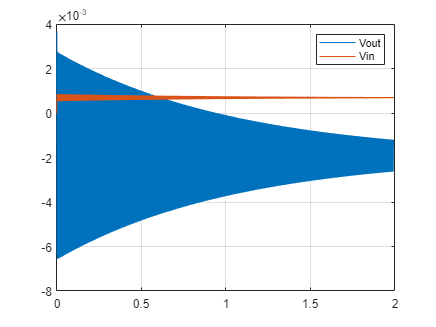


plot(sim.t,sim.X_t(sim.probe_id(1:2),:))
grid
legend('Vout','Vin')

netlist={
    'R1 0 e+ 1000'
    'C1 0 e+ 159e-9'
    'C2 e+ 1 159e-9 IC=1/3'
    'R2 1 out 1000'
    uA741('e+','e-','out')
    'R3 0 e- 1000'
    'R4 e- out 2000'
    '.tran tstop=10e-3 dtmax=1e-5 initTRAN=CI'
    '.probe out e+ e-'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
18 Resistor(s), 0 Inductor(s), 6 Capacitor(s), 5 Diode(s), 3 Current Source(s), 9 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

1230 time steps computed in 1.91421 seconds.


sim = struct with fields:
           X_t: [33×1230 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {3×1 cell}
      probe_id: [10 6 7]
         names: {1×33 cell}

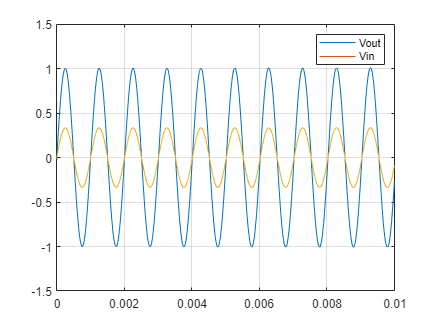


plot(sim.t,sim.X_t(sim.probe_id(1:3),:))
grid
legend('Vout','Vin')